# Model manipulation

**Vanja Vlasov**

In this tutorial, we will do a manipulation with the simple model of the first few reactions of the glycolisis metabolic pathway. 

Glycolysis is the metabolic pathway that occurs in most organisms in the cytosol of the cell. First, we will use the beginning of that pathway to create a simple constraint-based metabolic network (Figure 1).

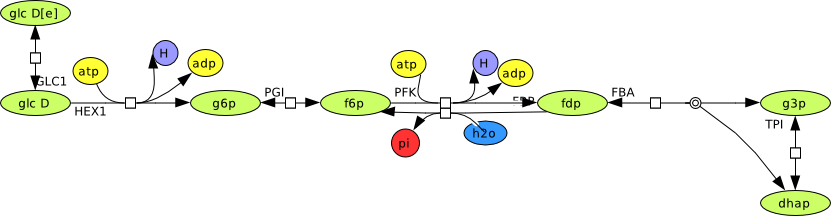

                                                                   Figure 1: A small metabolic network consisting of the seven reactions in the glycolisis pathway. 

At the beginning of the reconstruction, an integrity of the draft reconstruction must be initially assessed. The accuracy of the stochiometry, necessity of each reaction and metabolite, direction and reversibility of the reactions needed to be evaluated. 

After creating or loading the model, the model can be modified to simulate different conditions, such as:

- Creating, adding and handling reactions;

- Exchange, Sink and Demand reactions;

- Altering reaction bounds;

- Remove reactions and metabolites;

- Search for duplicates and comparison of two models;

- Changing the model objective;

- Changing the direction of reaction(s);

Start CobraToolbox

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   http://opencobra.github.io/cobratoolbox
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring solver environment variables ...
   - ILOG_CPLEX_PATH:  -

## Generate a network

A constraint-based metabolic model contains stoichiometric matrix with reactions and metabolites [1].

*S* is stoichiometric representation of metabolic networks corresponding to the reactions in the biochemical pathway. In an each column  of the *S *is a biochemical reaction and in each row is a precise metabolite. There is a stoichiometric coefficient of zero, which means that metabolite not participate in that distinct reaction. The coefficient also can be positive when the appropriate metabolite is produced, or negative for every metabolite depleted [1].

model.S = [-1, 0, 0 ,0 , 0, 0, 0;
            1, -1, 0, 0, 0, 0, 0;
            0, -1, 0,-1, 0, 0, 0;
            0, 1, 0, 1, 0, 0, 0;
            0, 1, 0, 1, 0, 0, 0;
            0, 1,-1, 0, 0, 0, 0;
            0, 0, 1,-1, 1, 0, 0;
            0, 0, 0, 1,-1,-1, 0;
            0, 0, 0, 0, 1, 0, 0;
            0, 0, 0, 0,-1, 0, 0;
            0, 0, 0, 0, 0, 1, 1;
            0, 0, 0, 0, 0, 1, -1];
model.lb = [0, 0, 0, 0, 0, 0, 0];
model.ub = [20, 20, 20, 20, 20, 20, 20];
model.mets = {'glc-D[e]'; 'glc-D'; 'atp'; 'H'; 'adp'; 'g6p';'f6p';'fdp'; 'pi';...
    'h2o'; 'g3p'; 'dhap'};
model.rxns = {'GLCt1'; 'HEX1'; 'PGI'; 'PFK'; 'FBP'; 'FBA'; 'TPI'};
sc =  [1, -1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0];
mets_length = length(model.mets);
rxns_length = length(model.rxns);

## Creating, adding and handling reactions

If we want to add a reaction to the model or modify an existing reaction we are using function addReaction.

We will show adding a new irreversible reaction using the formula and the list approach.

- The formula approach

model = addReaction(model, 'newRxn1', 'A + B -> 2 C + D');

newRxn1	A + B 	->	2 C + D 


Display of stoichiometric matrix after adding newRxn1:

full(model.S) 

ans =     -1     0     0     0     0     0     0     0
     1    -1     0     0     0     0     0     0
     0    -1     0    -1     0     0     0     0
     0     1     0     1     0     0     0     0
     0     1     0     1     0     0     0     0
     0     1    -1     0     0     0     0     0
     0     0     1    -1     1     0     0     0
     0     0     0     1    -1    -1     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0    -1     0     0     0


% one extra column is added(for added reaction) and 4 new rows(for A, B, C, D metabolites)

The following functions are used when we want to search reactions sequence in the model and change the order of the selected reaction.

rxnID = findRxnIDs(model, model.rxns);
model = moveRxn(model, 8, 1);

- The list approach

 The addReaction function has ability to recognize duplicate reactions when an order of metabolites and an abbreviation of the reaction are different.

model = addReaction(model, 'newRxn2', {'B', 'A', 'D', 'C'}, [-1; -1; 1; 2], false);

Checking if the number of the reaction increased by one and the number of metabolites was incremented by four (A,B,C,D).

assert(length(model.rxns) == rxns_length + 1);
assert(length(model.mets) == mets_length + 4);

## Exchange, Sink and Demand reactions

Specific type of reactions in the constraint-based models are reactions that are using and recycling accumulated metabolites, or producing required metabolites in the model.

- *Exchange reactions *-  Reactions added to the model to move metabolites across the created *in silico *compartments. Those compartments represent intra- and intercellular membranes.

- *Sink reactions* - The metabolites, produced in reactions that are outside of an ambit of the system or in unknown reactions, are supplied to the network with reversible sink reactions.

- *Demand reactions* - Irreversible reactions added to the model to consume metabolites that are deposited in the system.

There are two ways to implement that kind of reactions:

- **Use addReaction with documented function call:**

model = addReaction(model, 'EX_glc-D[e]', {'glc-D[e]'}, [-1]);

EX_glc-D[e]	glc-D[e] 	<=>	


    In the bigger networks we can find our exchange reactions with the following function:

[selExc] = findExcRxns(model, 0, 1)

selExc =    0
   0
   0
   0
   0
   0
   0
   0
   1


         2.  **To use exact function for particular reaction: addExchangeRxn, addSinkReactions, addDemandReaction.**

model = addExchangeRxn(model, {'glc-D'})

EX_glc-D	glc-D 	->	


model =        S: [16×10 double]
      lb: [0 0 0 0 0 0 0 0 0 0]
      ub: [20 20 20 20 20 20 20 20 20 20]
    mets: {16×1 cell}
    rxns: {10×1 cell}
     rev: [10×1 double]
       c: [10×1 double]


model = addSinkReactions(model, {'A', 'B', 'C', 'D'})

sink_A	A 	<=>	
sink_B	B 	<=>	
sink_C	C 	<=>	
sink_D	D 	<=>	


model =            S: [16×14 double]
          lb: [0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          ub: [20 20 20 20 20 20 20 20 20 20 20 20 20 20]
        mets: {16×1 cell}
        rxns: {14×1 cell}
         rev: [14×1 double]
           c: [14×1 double]
    rxnNames: {14×11 cell}


 model = addDemandReaction(model, {'dhap', 'g3p'})

DM_dhap	dhap 	->	
DM_g3p	g3p 	->	


model =            S: [16×16 double]
          lb: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          ub: [20 20 20 20 20 20 20 20 20 20 20 20 20 20 1000 1000]
        mets: {16×1 cell}
        rxns: {16×1 cell}
         rev: [16×1 double]
           c: [16×1 double]
    rxnNames: {16×11 cell}


## Setting ratio between the reactions and changing reactions boundary

It is important to emphasize that previous knowledge base informations should be taken into account. Most of them could disrupt future analysis of the model. 

For instance, if it is familiar that flux through one reaction is *X* times the flux through another reaction, it is recommended to specify that in your model. 

 E.g. $1\text{ }v\text{ }EX_glc−D\left\lbrack e\right\rbrack =2\text{ }v\text{ }EX_glc−D\text{ }$

model = addRatioReaction (model, {'EX_glc-D[e]', 'EX_glc-D'}, [1; 2]);

In order to respect the transport and exchange potential of a particular metabolite, or to resemble the different conditions in the model, we frequently need to set appropriate limits of the reactions.

model = changeRxnBounds(model, 'EX_glc-D[e]', -18.5, 'l');

## Remove reactions and metabolites

In order to detach reactions from the model, the following function has been used:

 model = removeRxns(model, {'EX_glc-D[e]', 'EX_glc-D', 'sink_A', 'sink_B', 'sink_C',...
     'sink_D', 'DM_dhap', 'DM_g3p'});

 assert(rxns_length + 1 == length(model.rxns)); 
 % The reaction length has been reevaluated 

Remove metabolites

  model = removeMetabolites(model, {'A', 'B', 'C', 'D'}, false);

For instance, in previous code the metabolites from 'newRxn1' were deleted, thus the reaction is still present in the model. To delete metabolites and reactions with zero rows and columns, following function has been used:

 model = removeTrivialStoichiometry(model)

model =            S: [12×7 double]
          lb: [0 0 0 0 0 0 0]
          ub: [20 20 20 20 20 20 20]
        mets: {12×1 cell}
        rxns: {7×1 cell}
         rev: [7×1 double]
           c: [7×1 double]
    rxnNames: {7×11 cell}
           b: [0 0 0 0 0 0 0 0 0 0 0 0]
     metName: {[]  []  []  []  []  []  []  []  []  []  []  []}
        note: 'EX_glc-D[e] andEX_glc-Dare set to have a ratio of1:2.'


## Search for duplicates and comparison of two models

How genome-scale metabolic models are expanding every day [2], the need for comparison and merge of them is also spreading. 

The elementary functions for the model manipulation, besides main actions, simultaneously perform the structural analysis and comparison (e.g. addReaction). Likewise, there are additional functions that are only dealing with analysing similarities and differences within and between the models.

- Checking for reaction duplicates by reaction abbreviation, by using method 'S' that will not detect reverse reactions, and method 'FR' that will neglect reactions direction:

[model, removedRxn, rxnRelationship] = checkDuplicateRxn(model, 'S', 1, 1);

Checking for reaction duplicates by stoichiometry ...
 no duplicates found.


Adding duplicate reaction to the model:

model = addReaction(model, 'GLCt1_duplicate_reverse', model.mets, sc, 0, 0, 20,0,...
    'temp', [], [], [], 1, 0);

fprintf('>> Detecting duplicates with using S method\n');

>> Detecting duplicates with using S method


method = 'S'; 
%will not be removed as does not detect reverse reaction
[model,removedRxn, rxnRelationship] = checkDuplicateRxn(model, method, 1, 1);

Checking for reaction duplicates by stoichiometry ...
 no duplicates found.


assert(rxns_length + 1 == length(model.rxns)); 
% The reaction length has been reevaluated

fprintf('>> Detecting duplicates with using FR method\n');

>> Detecting duplicates with using FR method


method = 'FR';
%will be removed as detects reverse reaction
[model, removedRxn, rxnRelationship] = checkDuplicateRxn(model, method, 1, 1);

Checking for reaction duplicates by stoichiometry (up to orientation) ...
     Keep: 	GLCt1	glc-D[e] 	->	glc-D 
Duplicate: 	GLCt1_duplicate_reverse	glc-D 	->	glc-D[e] 


assert(rxns_length == length(model.rxns));

- Function checkCobraModelUnique marks the reactions and metabolites that are not unique in the model.

model = checkCobraModelUnique(model, false)

model =            S: [12×7 double]
          lb: [0 0 0 0 0 0 0]
          ub: [20 20 20 20 20 20 20]
        mets: {12×1 cell}
        rxns: {7×1 cell}
         rev: [7×1 double]
           c: [7×1 double]
    rxnNames: {7×11 cell}
           b: [0 0 0 0 0 0 0 0 0 0 0 0]
     metName: {[]  []  []  []  []  []  []  []  []  []  []  []}
        note: 'EX_glc-D[e] andEX_glc-Dare set to have a ratio of1:2.'


## Changing the model's objective

Simulating different conditions in the model is often necessery in favor of performing calculations that investigate a specific objective. One of the elementary objectives is optimal growth [3]. Model can be modified to get different conditions with changing the model objective:

modelNew = changeObjective(model, 'GLCt1', 0.5);

% multiple rxns, default coefficient (1)
modelNew = changeObjective(model, {'PGI'; 'PFK'; 'FBP'});


## The direction of reactions 

When reaction is reversible and we want to remove it, it is necessary to first change the reverse sign and than remove reaction afterwards. 

fprintf('>> Converting to Irreversible\n');

>> Converting to Irreversible


load('testModelManipulation.mat', 'model', 'modelIrrev');
[testModelIrrev, matchRev, rev2irrev, irrev2rev] = convertToIrreversible(model);

Following function is comparing the differences and similarities between two models:

assert(isSameCobraModel(modelIrrev, testModelIrrev));

Converting to reversible

fprintf('>> Convert to Reversible\n');

>> Convert to Reversible


testModelRev = convertToReversible(testModelIrrev);
load('testModelManipulation.mat','modelRev');

assert(isSameCobraModel(modelRev, testModelRev)); 

## References 

[1] Orth, J. D., Thiele I., and Palsson, B. Ø. (2010). What is flux balance analysis? *Nat. Biotechnol., 28*(3), 245–248.

[2] Feist, A. M., Palsson, B. (2008). The Growing Scope of  Applications of Genome-scale Metabolic Reconstructions: the case of *E. coli*. *Nature Biotechnology, 26*(6), 659–667.

[3] Feist, A. M., Palsson, B. O. (2010). The Biomass Objective Function. *Current Opinion in Microbiology, 13*(3), 344–349.